## Perfomance Specification

clear; clc;
tr = 0.6; % rise time (<0.3)
ts = 3; % settling time (<3)
Mp = 10; % overshoot (<7%)


alpha_percentage = 4 % settling time

alpha_percentage = 4



omega_n = 1.8/tr % natural frequency

omega_n = 3

zeta = sqrt((log(Mp) / -pi)^2 / (1 + (log(Mp) / -pi)^2)) % needs to be smaller than Mp

zeta = 0.5912

sigma = (-log(alpha_percentage/100))/ts

sigma = 1.0730

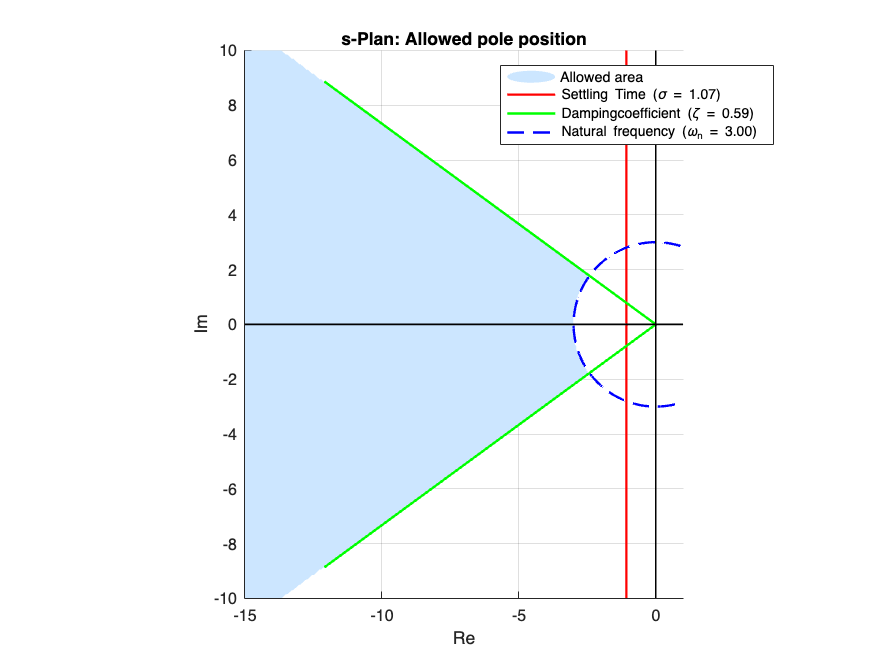




% ---------------------- figur -------------------
% Beregn vinkel
theta = asin(zeta);

% Ny grænse for real-akse
xMin = -15;
xMax = 1;
yMin = -10;
yMax = 10;

% Opret gitter
re = linspace(xMin, xMax, 300);
im = linspace(yMin, yMax, 400);
[Re, Im] = meshgrid(re, im);
S = Re + 1i * Im;

% Krav
settling = real(S) <= -sigma;
angle = abs(imag(S) ./ real(S)) <= tan(theta) & real(S) <= 0;
rise = abs(S) >= omega_n;
combined = settling & angle & rise;

figure;
hold on;
grid on;
axis equal;

% Plot tilladt område (kombineret constraint): lyseblå uden kant
fill_region = contourf(Re, Im, combined, [1 1], 'FaceColor', [0.8 0.9 1], ...
    'EdgeColor', 'none', 'DisplayName','Allowed area');
alpha(0.5);

% Settling time-linje (σ): Rød
plot([-sigma -sigma], [yMin yMax], 'r-', 'LineWidth', 1.5, ...
    'DisplayName', sprintf('Settling Time (\\sigma = %.2f)', sigma));

% Dæmpningslinjer (ζ): Grøn
r = abs(xMin);
plot([0 -r*cos(theta)], [0 r*sin(theta)], 'g-', 'LineWidth', 1.5, ...
    'DisplayName', sprintf('Dampingcoefficient (\\zeta = %.2f)', zeta));
plot([0 -r*cos(theta)], [0 -r*sin(theta)], 'g-', 'LineWidth', 1.5, 'HandleVisibility','off');

% Rise time cirkel (ωₙ): Blå streg
theta_circle = linspace(0, 2*pi, 200);
plot(omega_n*cos(theta_circle), omega_n*sin(theta_circle), 'b--', 'LineWidth', 1.5, ...
    'DisplayName', sprintf('Natural frequency (\\omega_n = %.2f)', omega_n));

% Akser (sort, men ikke vist i legend)
plot([xMin xMax], [0 0], 'k-', 'LineWidth', 1, 'HandleVisibility','off'); % Re-akse
plot([0 0], [yMin yMax], 'k-', 'LineWidth', 1, 'HandleVisibility','off'); % Im-akse

% Labels og titel
xlabel('Re');
ylabel('Im');
title('s-Plan: Allowed pole position');
legend('show', 'Location', 'best');

% Skala
xlim([xMin xMax]);
ylim([yMin yMax]);

hold off;

## Linearisering via jacobiant

%Define system
m_c = 0.5;      % Mass of cart [kg]
m_p = 0.083;    % Mass of pendulum [kg]
l = 0.357;      % Length of pendulum [m]
g = 9.81;       % Gravitational acceleration [m/s^2]
b_c = 5;        % Linear damping coefficient of the cart [N/(m/s)]
b_p = 0.0012;   % Rotational damping coefficient of the pendulum [Nm/(rad/s)
I = (1/3)*m_p*l^2;     % inertia of pendulum

syms x dx ddx tau_m F theta dtheta ddtheta


sinTheta = sin(theta); % mads
cosTheta = cos(theta); % mads

q = [x; theta]; % mads
dq = [dx; dtheta]; % mads

% Mass-matrice
M = [m_c + m_p,  -m_p*l*cosTheta;
     -m_p * l * cosTheta, m_p * l^2 + I];
M_inv = inv(M);

% Right hand side (forces applied on system)
RHS = [F - b_c * dx - m_p * l * sinTheta * dtheta^2;
       -b_p * dtheta + m_p * g * l * sinTheta];

% isolate ddq -> M*ddq=RHS
ddq = M_inv*RHS;


tSign = @(val) atan(100 * val); %Custom sign-method (continues function for differential purpose)




%Beginning of Control system
%Linearization & state-space
%Constants when the system is "stable"
cx_c = 0;
c_theta = 0; % skal måske ændres pi
cdx_c = 0;
cdt_p = 0;
cF_c = 0;

% Define system dynamics (f)
f = [dq; ddq];

% Compute the Jacobian matrix (A) with respect to the states
A = jacobian(f, [x, theta, dx, dtheta]);

% Compute the Jacobian matrix (B) with respect to the input
B = jacobian(f, F);

% Substitute equilibrium values into the Jacobians
A = double(subs(A, [x, theta, dx, dtheta, tau_m], [cx_c, c_theta, cdx_c, cdt_p, cF_c]))

A =          0         0    1.0000         0
         0         0         0    1.0000
         0    1.1727   -9.6015   -0.0048
         0   23.0729  -20.1713   -0.0953


B = double(subs(B, [x, theta, dx, dtheta, tau_m], [cx_c, c_theta, cdx_c, cdt_p, cF_c]))

B =          0
         0
    1.9203
    4.0343


C = [0 1 0 0]; % output -> theta
D = 0;

% lineariseret system
sys = ss(A, B, C, D)


sys =
 
  A = 
              x1         x2         x3         x4
   x1          0          0          1          0
   x2          0          0          0          1
   x3          0      1.173     -9.602  -0.004841
   x4          0      23.07     -20.17   -0.09525
 
  B = 
          u1
   x1      0
   x2      0
   x3   1.92
   x4  4.034
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


G = tf(sys);


### Open loop analyze

Det ses på Root Locus, at systemet er ustabilt, da det har 1 pol i højre halvplan, som VIL bevæge sig mod det ene nulpunkt.

Derfor har man brug for at tilføje en PID-controller. Ved tilføjelse, tilføjer man to nye nuller, som man SELV bestemmer hvor skal ligge. Desuden tilføjes der også en pol, som placeres i origo.

Først analyseres open-loop af systemet. Hvordan input påvirker output, uden brug af feedback

Poler viser systemets stabilitet og hvor hurtigt det reagere

Nuller viser dets respons'

% --- Open Loop Analyse ---
% Vis overføringsfunktionen
disp('--- Transfer function G(s) ---')

--- Transfer function G(s) ---


G


G =
 
         4.034 s + 7.621e-15
  ---------------------------------
  s^3 + 9.697 s^2 - 22.26 s - 197.9
 
Continuous-time transfer function.
Model Properties


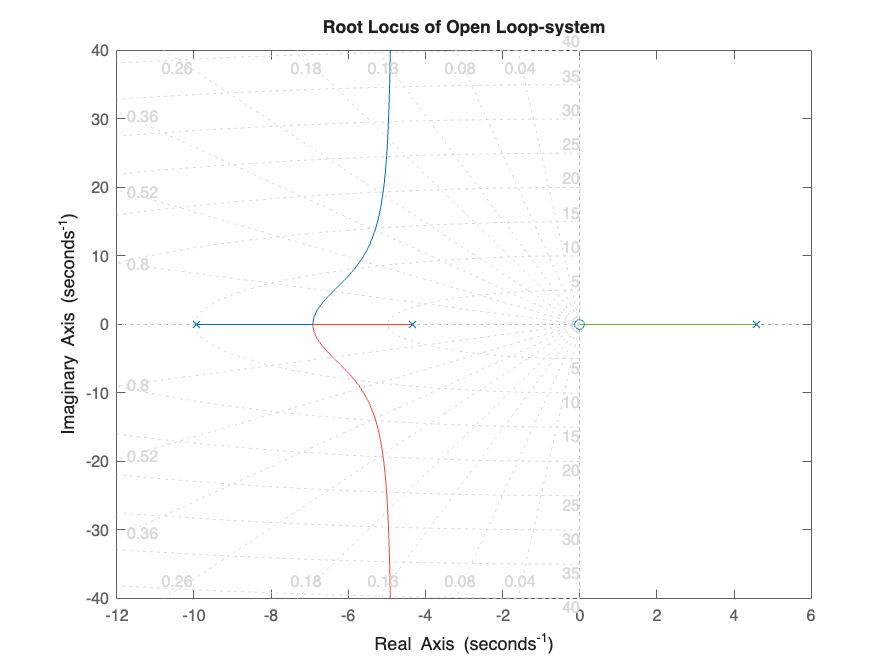


% Plot rodsted (root locus)
figure;
rlocus(G)
title('Root Locus of Open Loop-system')
grid on


% Udskriv poler
poles = pole(G);
disp('--- Poles in open loop G(s) ---')

--- Poles in open loop G(s) ---


disp(poles)

   -9.9315
    4.5826
   -4.3478




% Udskriv nulpunkter
zeroes = zero(G);
disp('--- Zeroes ni open loop G(s) ---')

--- Zeroes ni open loop G(s) ---


disp(zeroes)

  -1.8890e-15



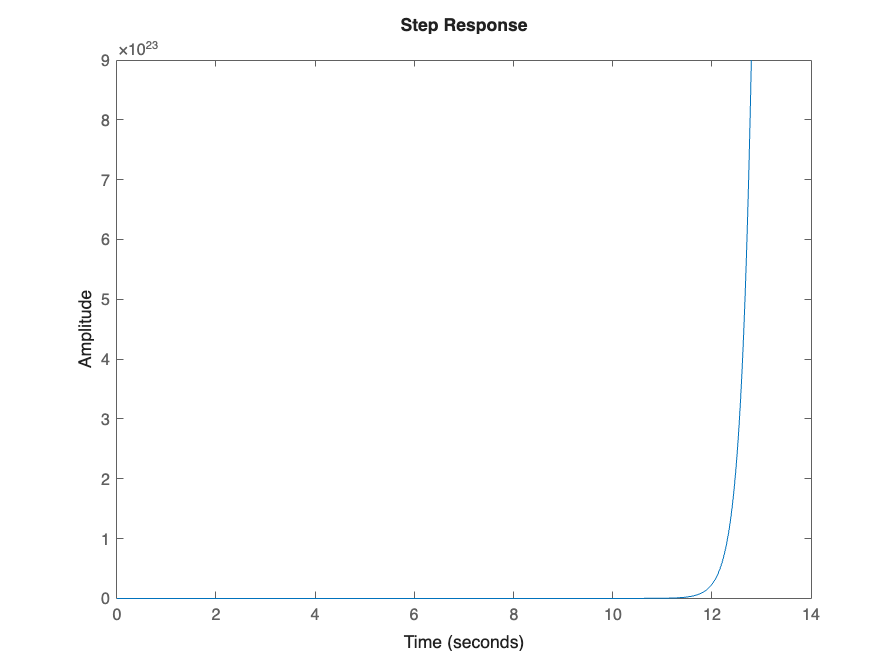


step(G);

disp('Step Response of Open Loop-system')

Step Response of Open Loop-system


disp(zeroes)

  -1.8890e-15



På rootlocus kan det ses en pol er i højre halvplan, og når forstærkningen K øges, så vil polen ALDRIG nå til være halvplan, da den bevæger sig mod nullen, som ligger i 0,0

## Design af PID

### Sæt poler

PID-controller kan skrives på følgende måder:

- 
$$C\left(s\right)=\frac{\left(s+{\mathrm{nul}}_1 \right)\left(s+{\mathrm{nul}}_2 \right)}{s}$$


- 
$$C\left(s\right)=K_p +\frac{K_i }{s}+K_d s$$


- 
$$C\left(s\right)=\frac{K_d s^2 +K_p s+K_i }{s}$$


For at få den ustabile pol til at bevæge sig ind i venstre halvplan bruges PID.

Der skal nu placeres to nuller via den "første" formel. Disse nuller skal placeres således at 1 pol bevæger sig mod uendelig, 1 pol bevæger sig mod et nulpunkt og den sidste pol bevæger sig mod venstre halvplan.

Poler:

- langt til venstre = hurtig respons

- Tæt ved imaginæraksen = langsom eller oscillerende respons

Nuller: 

- "magneter" - tiltrækker poler

s = tf('s')


s =
 
  s
 
Continuous-time transfer function.
Model Properties


con = (s+7)*(s+5)/s % kd=1, kp=20, ki=96          valgt nul-placeringer i -1 og -5 og lagt pol i origo


con =
 
  s^2 + 12 s + 35
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


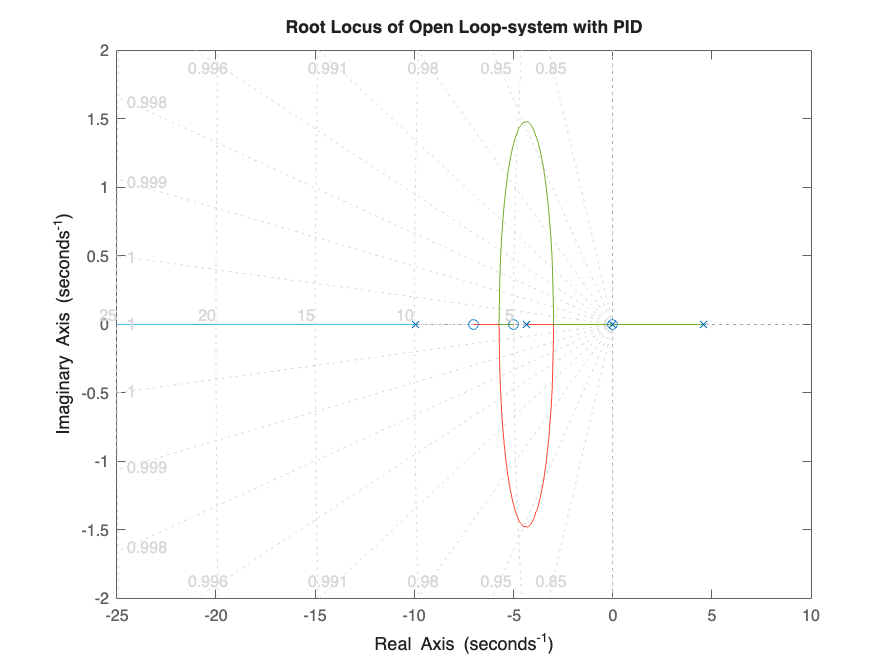

% Plot rodsted (root locus)
figure;
rlocus(con*G)
title('Root Locus of Open Loop-system with PID')
grid on

poles = pole(con*G)

poles =          0
   -9.9315
    4.5826
   -4.3478


zeroes = zero(con*G)

zeroes =    -7.0000
   -5.0000
   -0.0000


Det ses på root locus, at polen i højre halvplan vil bevæge sig ind mod venstre, da den blvier tiltrukket af et nul. Dvs. jo mere man øger forstærkningen K, jo tættere vil den komme nullen.

Ud fra følgende formel: $C\left(s\right)=\frac{K_d s^2 +K_p s+K_i }{s}$, kan K-værdier findes

% sæt K-værdier ud fra transfer function
[num, den] = tfdata(con, 'v');  % Få tæller og nævner som vektorer

Kp = num(2)        % koefficient for s

Kp = 12

Ki = num(3)        % konstantled

Ki = 35

Kd = num(1)        % koefficient for s^2

Kd = 1

### Omskriv transferfunktion og K-værdier

Disse værdier kan omskrives til $K,T_i \;\textrm{og}\;T_d$, som bruges i den "Ideelle" formel, hvor der fås en samlet K-værdi

Ved hjælp af K, kan man flytte hele root locus, og derved ændre hele dynamikken.


$$C\left(s\right)=K\left(1+\frac{1}{T_i s}+T_d s\right)$$


- 
$$K_p =K$$


- 
$$K_i =\frac{K}{T_i }$$


- 
$$K_d =K*T_d$$


K-værdien er en samlet værdi for alle K-led, med denne værdi, er det nemt at "forstærke" sit system og se om polerne flytter sig i den rigtige retning.

K = Kp

K = 12

Ti = K/Ki

Ti = 0.3429

Td = Kd/K

Td = 0.0833


K = 75 % ændre denne værdi

K = 75

con = K*(1+1/(Ti*s)+Td*s)


con =
 
  2.143 s^2 + 25.71 s + 75
  ------------------------
          0.3429 s
 
Continuous-time transfer function.
Model Properties


% sæt K-værdier ud fra transfer function
[num, den] = tfdata(con, 'v');  % Få tæller og nævner som vektorer

% --- EFTER FORSTÆRKNING --- 
Kp = num(2)        % koefficient for s

Kp = 25.7143

Ki = num(3)        % konstantled

Ki = 75

Kd = num(1)        % koefficient for s^2

Kd = 2.1429

### Closed-loop analyse

Se nu hvordan polerne bevæger sig mod venstre i closed loop

T_cl = feedback(con*G, 1) % closed loop


T_cl =
 
        8.645 s^3 + 103.7 s^2 + 302.6 s + 5.716e-13
  --------------------------------------------------------
  0.3429 s^4 + 11.97 s^3 + 96.11 s^2 + 234.7 s + 5.716e-13
 
Continuous-time transfer function.
Model Properties


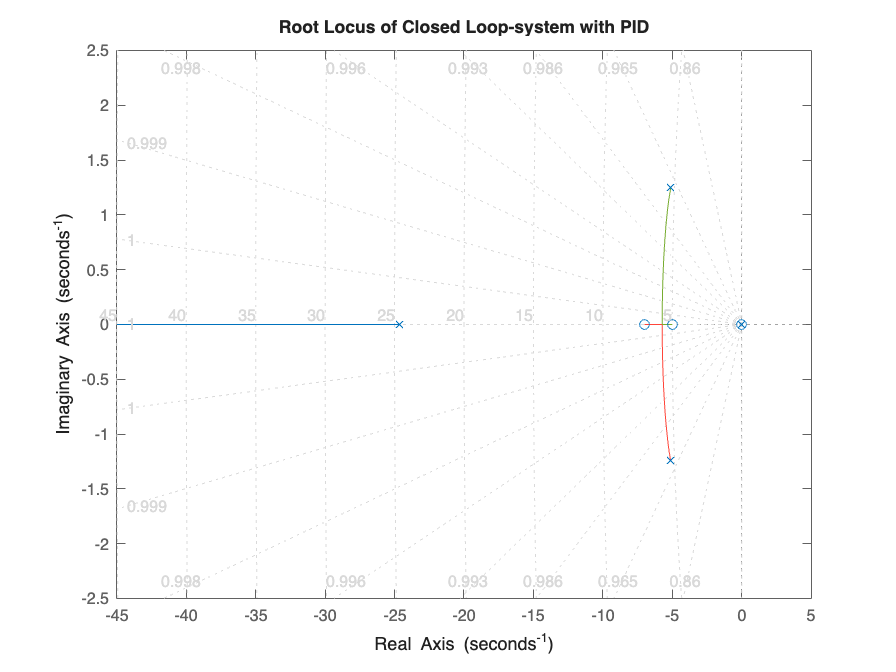

% Plot rodsted (root locus)
figure;
rlocus(T_cl)
title('Root Locus of Closed Loop-system with PID')
grid on


% Udskriv poler
newPoles = pole(T_cl);
disp('--- Poles in closed loop G(s) ---')

--- Poles in closed loop G(s) ---


disp(newPoles)

 -24.6752 + 0.0000i
  -5.1179 + 1.2460i
  -5.1179 - 1.2460i
  -0.0000 + 0.0000i




% Udskriv nulpunkter
newZeroes = zero(T_cl);
disp('--- Zeroes in closed loop G(s) ---')

--- Zeroes in closed loop G(s) ---


disp(newZeroes)

   -7.0000
   -5.0000
   -0.0000



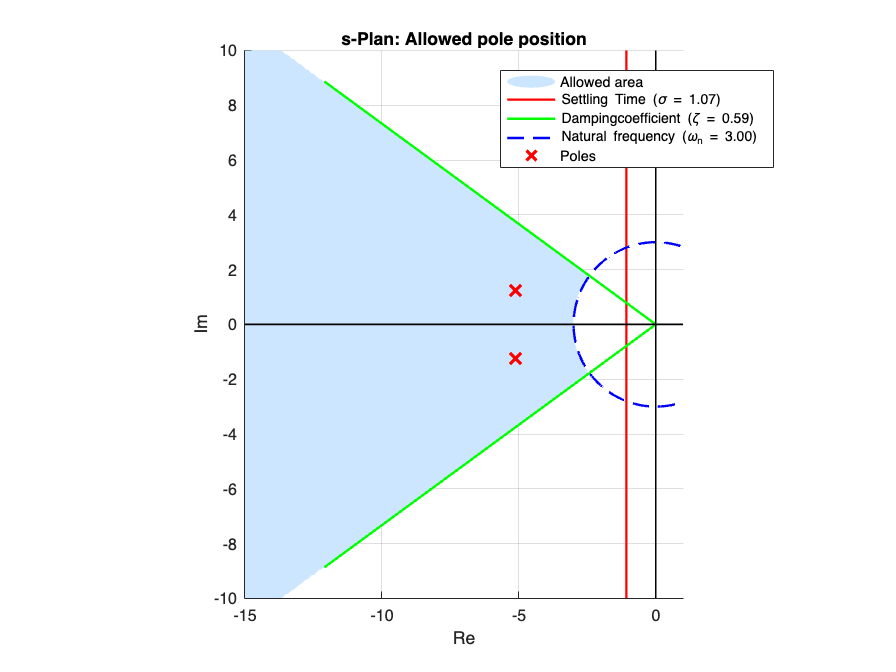



% ----- se om poler er indenfor specificeret område -----
% Beregn vinkel
theta = asin(zeta);

% Ny grænse for real-akse
xMin = -15;
xMax = 1;
yMin = -10;
yMax = 10;

% Opret gitter
re = linspace(xMin, xMax, 300);
im = linspace(yMin, yMax, 400);
[Re, Im] = meshgrid(re, im);
S = Re + 1i * Im;

% Krav
settling = real(S) <= -sigma;
angle = abs(imag(S) ./ real(S)) <= tan(theta) & real(S) <= 0;
rise = abs(S) >= omega_n;
combined = settling & angle & rise;

figure;
hold on;
grid on;
axis equal;

% Plot tilladt område (kombineret constraint): lyseblå uden kant
fill_region = contourf(Re, Im, combined, [1 1], 'FaceColor', [0.8 0.9 1], ...
    'EdgeColor', 'none', 'DisplayName','Allowed area');
alpha(0.5);

% Settling time-linje (σ): Rød
plot([-sigma -sigma], [yMin yMax], 'r-', 'LineWidth', 1.5, ...
    'DisplayName', sprintf('Settling Time (\\sigma = %.2f)', sigma));

% Dæmpningslinjer (ζ): Grøn
r = abs(xMin);
plot([0 -r*cos(theta)], [0 r*sin(theta)], 'g-', 'LineWidth', 1.5, ...
    'DisplayName', sprintf('Dampingcoefficient (\\zeta = %.2f)', zeta));
plot([0 -r*cos(theta)], [0 -r*sin(theta)], 'g-', 'LineWidth', 1.5, 'HandleVisibility','off');

% Rise time cirkel (ωₙ): Blå streg
theta_circle = linspace(0, 2*pi, 200);
plot(omega_n*cos(theta_circle), omega_n*sin(theta_circle), 'b--', 'LineWidth', 1.5, ...
    'DisplayName', sprintf('Natural frequency (\\omega_n = %.2f)', omega_n));

% Akser (sort, men ikke vist i legend)
plot([xMin xMax], [0 0], 'k-', 'LineWidth', 1, 'HandleVisibility','off'); % Re-akse
plot([0 0], [yMin yMax], 'k-', 'LineWidth', 1, 'HandleVisibility','off'); % Im-akse

% --- TILFØJ POLE-PLOT HER ---
% Eksempel: indsatte poler (komplekse og reelle)
% Rediger nedenstående linje med dine faktiske poler
poles = newPoles(1:3); 

% Plot poler som røde krydser
plot(real(poles), imag(poles), 'rx', 'MarkerSize', 10, 'LineWidth', 2, ...
    'DisplayName', 'Poles');

% Labels og titel
xlabel('Re');
ylabel('Im');
title('s-Plan: Allowed pole position');
legend('show', 'Location', 'best');

% Skala
xlim([xMin xMax]);
ylim([yMin yMax]);

hold off;

## Analyse af steprespons

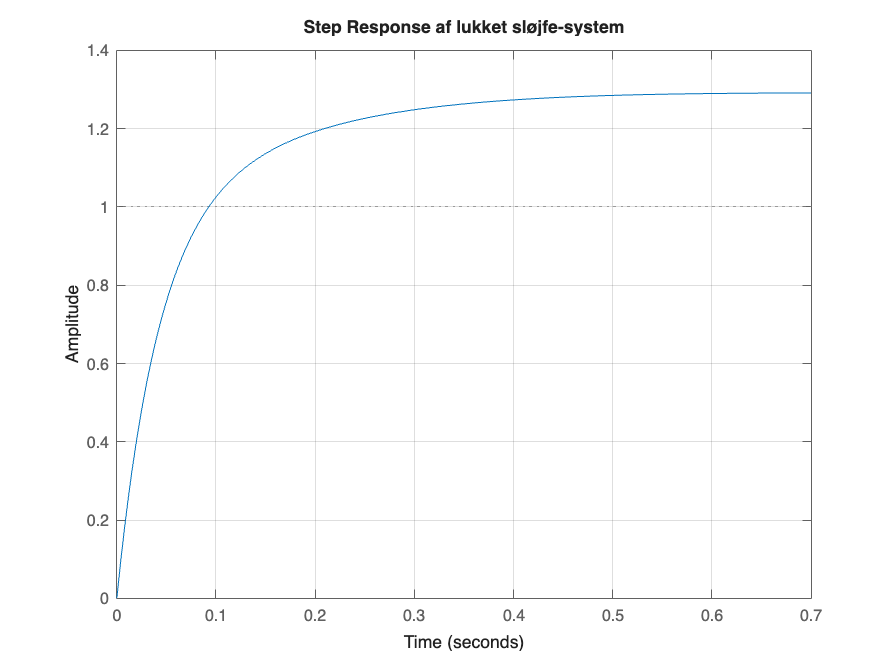

% Plot step-respons
figure;
step(T_cl);
title('Step Response af lukket sløjfe-system');
grid on;

% Udrul information om step-respons
S = stepinfo(T_cl);
%disp('Step Response Information:');
%disp(S);

% Uddrag specifikke parametre
riseTime = S.RiseTime;
overshoot = S.Overshoot;
settlingTime = S.SettlingTime;

% Udskriv resultater
disp("Compare new system to perfomance specification:")

Compare new system to perfomance specification:


fprintf('Responstid (Rise Time): %.4f s <= %.1f s\n', riseTime, tr);

Responstid (Rise Time): 0.1622 s <= 0.6 s


fprintf('Oversving (Overshoot): %.2f%% <= %.2f%%\n', overshoot, Mp);

Oversving (Overshoot): 0.20% <= 10.00%


fprintf('Settling Time: %.4f sekunder <= %.1f sekunder\n', settlingTime, ts);

Settling Time: 0.3498 sekunder <= 3.0 sekunder
